# Collect and Interpret Experiment Data

cd('/Users/davisreina-guerra/Desktop/Monster Data Analysis/23831')

Session1 = load("""23831_Day1"".mat")

Session1 = struct with fields:
    Session_average_table: [1×13 table]
       Session_data_table: [10×13 table]


Session2 = load("""23831_Day2"".mat")

Session2 = struct with fields:
    Session_average_table: [1×13 table]
       Session_data_table: [10×13 table]


% Session3 = load('""')
% Session4 = load('""')
% Session5 = load('""')
% Session6 = load('""')
% Session7 = load('""')

Session1_Data = Session1.Session_data_table

Session1_Data = 10×13 table
    Time_enter_trial_variable    Time_engage_trial_variable    Time_reward_trial_variable    Time_exit_trial_variable    Failed_before_engage    Failed_after_engage    Failed_in_general    Succeeded    Total_trial_duration    Latency_to_engage    Duration_engage_to_success    Escape_duration_after_success    Engage_to_escape_duration_when_successful
    _________________________    __________________________    __________________________    ________________________    ____________________    ___________________    _________________    _________    ____________________    ____________

Session2_Data = Session2.Session_data_table

Session2_Data = 10×13 table
    Time_enter_trial_variable    Time_engage_trial_variable    Time_reward_trial_variable    Time_exit_trial_variable    Failed_before_engage    Failed_after_engage    Failed_in_general    Succeeded    Total_trial_duration    Latency_to_engage    Duration_engage_to_success    Escape_duration_after_success    Engage_to_escape_duration_when_successful
    _________________________    __________________________    __________________________    ________________________    ____________________    ___________________    _________________    _________    ____________________    ____________

% Session3_Data = Session3.Session_data_table
% Session4_Data = Session4.Session_data_table
% Session5_Data = Session5.Session_data_table
% Session6_Data = Session6.Session_data_table
% Session7_Data = Session7.Session_data_table

Session1_Averages = table2array(Session1.Session_average_table)

Session1_Averages = 	1.0e+04 *

    0.1544    0.6567       NaN    1.7571    0.0004    0.0010    0.0010         0    1.6027    0.4324       NaN       NaN       NaN


Session2_Averages = table2array(Session2.Session_average_table)

Session2_Averages = 	1.0e+04 *

    0.1544    0.6567       NaN    1.7571    0.0004    0.0010    0.0010         0    1.6027    0.4324       NaN       NaN       NaN


% Session3_Averages = Session3.Session_average_table
% Session4_Averages = Session4.Session_average_table
% Session5_Averages = Session5.Session_average_table
% Session6_Averages = Session6.Session_average_table
% Session7_Averages = Session7.Session_average_table

Experiment_data = [Session1_Averages; Session2_Averages]

Experiment_data = 	1.0e+04 *

    0.1544    0.6567       NaN    1.7571    0.0004    0.0010    0.0010         0    1.6027    0.4324       NaN       NaN       NaN
    0.1544    0.6567       NaN    1.7571    0.0004    0.0010    0.0010         0    1.6027    0.4324       NaN       NaN       NaN


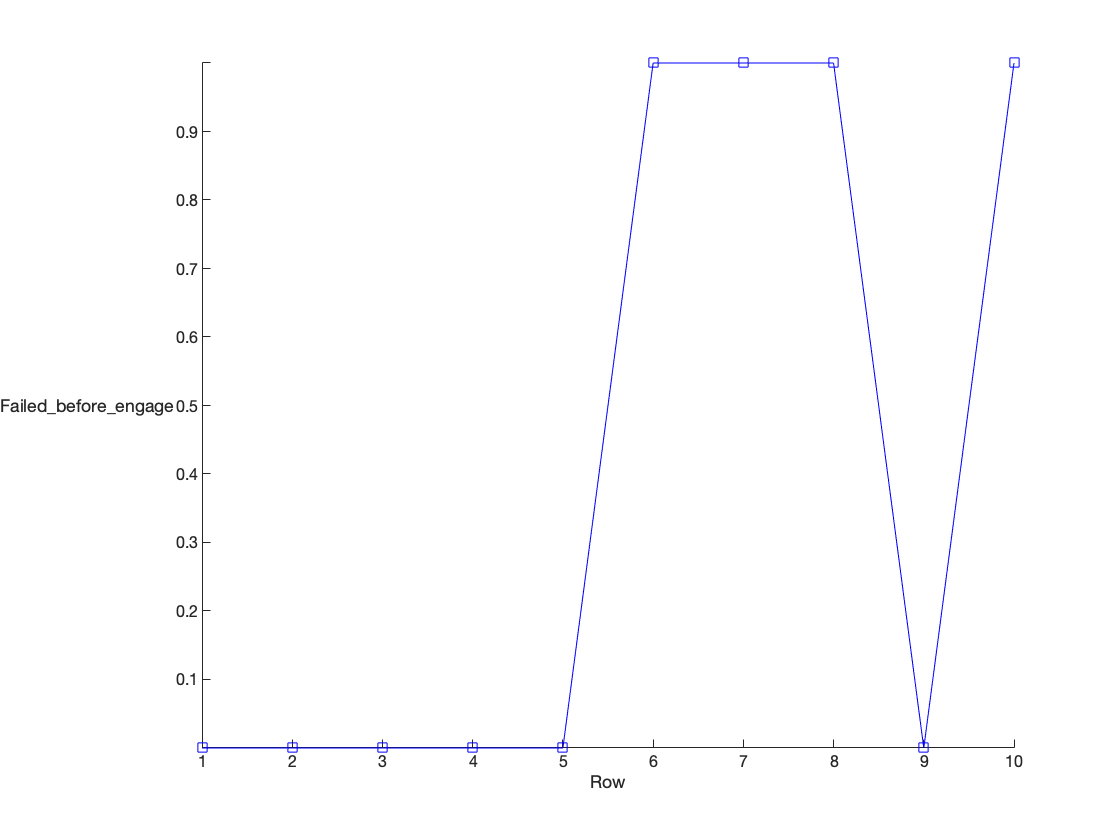


stackedplot(Session1_Data(:,"Failed_before_engage"), "-squareb")